% === 参数设置 ===
close all; clear; clc
j = sqrt(-1);

fs = 80e6;           % 采样频率
ts = 1/fs;
B = 10e6;            % 带宽
fc = 40e6;           % 中心频率
label = 2;

% === LFM脉冲 ===
taup = 10e-6;        % LFM脉宽
Ntau = round(taup * fs);
ttau = (-Ntau/2 : Ntau/2-1) * ts;
lfm = exp(1j*pi*B/taup * ttau.^2);  % 基带LFM脉冲

% === 多脉冲参数 ===
Np = 16;                 % 脉冲个数
PRI = 200e-6;            % 脉冲重复间隔 200 μs
PRI_samp = round(PRI * fs);   % 每个PRI的采样点
N_total = Np * PRI_samp;      % 总采样点数
t_total = (0:N_total-1) * ts; % 时间轴

% === 构造发射信号 ===
tx = zeros(1, N_total);
target_start_idx_in_PRI = 5e3

target_start_idx_in_PRI = 5000

for k = 0:Np-1
    start_idx = k * PRI_samp + target_start_idx_in_PRI;
    tx(start_idx : start_idx + Ntau - 1) = lfm;
end

% === 模拟噪声与干扰 ===
SNR = 15;
JNR = 15;
Bj = 5e6;  % 扫频带宽
fjc = 0;   % 干扰中心频率
data_num = 3 %干扰样本数

data_num = 3

As = 10^(SNR/20);
Aj = 10^(JNR/20);

jam = zeros(data_num,N_total);
repetition_times_arr=[4,3,2,1];   %重复次数
period_arr=[5e-6,10e-6];    %采样脉冲周期 taup / period = 4 或 2，表示采样次数
duty_arr=[20,25,33.33,50];  %占空比

for m = 1:data_num
    % 生成高斯白噪声
    sp = randn([1,N_total]) + 1j*randn([1,N_total]);
    sp = sp / std(sp);
    white_noise = sp;

    % --- 1. 从数组中随机选择ISRJ参数 ---
    index1 = 1 + round(rand(1,1));          % 随机选择周期 (索引1或2)
    sampling_period = period_arr(index1);
    
    index2 = 1 + round(rand(1,1)*3);      % 随机选择占空比 (索引1到4)
    sampling_duty = duty_arr(index2);
    
    % 关键：转发次数与占空比通过同一个索引index2关联
    repetition_times = repetition_times_arr(index2);
    
    fprintf('--- 干扰样本 %d 参数 ---\n', m);
    fprintf('采样周期: %.1f us\n', sampling_period*1e6);
    fprintf('占空比: %.2f %%\n', sampling_duty);
    fprintf('转发次数: %d\n', repetition_times);
    
    % --- 2. 生成采样方波并对LFM信号进行切片 ---
    % 使用与LFM脉冲相同的时间轴ttau来生成方波
    squa = (square((1/sampling_period)*2*pi*ttau, sampling_duty) + 1) / 2; % 单极性方波

    % 得到被采样/切片的LFM信号，这是我们要转发的干扰基本单元
    jam_slice = lfm .* squa;
    
    % --- 3. 在一个PRI内生成转发干扰串 ---
    % 我们首先在一个PRI内生成干扰，然后将其复制到所有PRI
    jam_pri = zeros(1, PRI_samp);
    
    % 计算每次转发的固定延迟时间，即采样脉冲的宽度 ("on" time)
    delay_time = sampling_period * (sampling_duty / 100)*2;
    delay_samp = round(delay_time * fs); % 转换为采样点数
    
    fprintf('每次转发延迟: %.1f us (%d samples)\n\n', delay_time*1e6, delay_samp);

    % 循环多次转发，形成一串等间隔的假目标
    for i = 1:repetition_times
        % 干扰切片的起始位置 = 真实目标位置 + 累积的延迟
        left_range = target_start_idx_in_PRI + i * delay_samp;
        right_range = left_range + Ntau - 1;
        
        % 检查是否超出当前PRI的范围，避免索引错误
        if right_range <= PRI_samp
            jam_pri(left_range:right_range) = jam_pri(left_range:right_range) + Aj * jam_slice;
        end
    end

    % --- 4. 将单个PRI的干扰模板复制到整个信号长度 ---
    jam_signal = repmat(jam_pri, 1, Np)+sp;

    % --- 5. 保存生成的干扰样本 ---
    jam(m, :) = jam_signal;
    % =========================================================================

end

--- 干扰样本 1 参数 ---


采样周期: 5.0 us


占空比: 25.00 %


转发次数: 3


每次转发延迟: 2.5 us (200 samples)



--- 干扰样本 2 参数 ---


采样周期: 10.0 us


占空比: 25.00 %


转发次数: 3


每次转发延迟: 5.0 us (400 samples)



--- 干扰样本 3 参数 ---


采样周期: 10.0 us


占空比: 25.00 %


转发次数: 3


每次转发延迟: 5.0 us (400 samples)



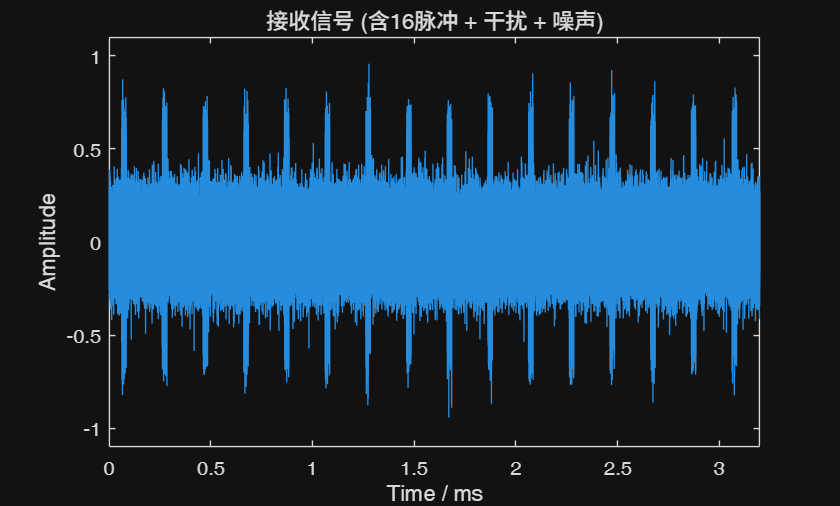


% --- 加入目标与干扰 ---
range_tar = 1 + round(rand(1)*4000);
pure_echo = As*tx;
rx = As*tx + jam_signal + white_noise;
rx = rx / max(abs(rx));

figure;
plot(t_total*1e3, real(rx));
axis([0 3.2 -1.1 1.1])
xlabel('Time / ms'); ylabel('Amplitude');
title('接收信号 (含16脉冲 + 干扰 + 噪声)');

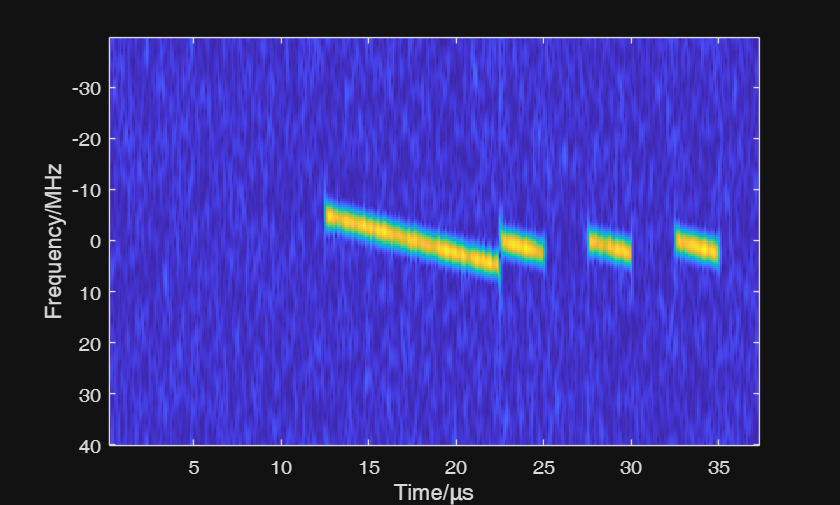


figure;
[S,F,T] = spectrogram(rx(4000:7000),32,32-8,200,fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
% axis([0 100 -20 20])
ylabel('Frequency/MHz'); xlabel('Time/μs');


% === 匹配滤波（脉冲压缩） ===
h = conj(flip(lfm));
y = conv(rx, h);
env = abs(y);

% === 脉冲积累（非相干示例） ===
env_mat = reshape(env(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
env_sum = abs(sum(env_mat, 2));  % 直接复数相加再取幅度
nenv_mat = reshape(y(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
nenv_sum = sum(nenv_mat, 2); % 非相干积累

% 距离轴
c = 3e8;
rng_axis = (0:PRI_samp-1)*c/(2*fs);



